# **demo06 of Im2mesh package**

demo06 - Demonstrate thresholds in polyline smoothing

Author: Jiexian Ma, mjx0799@gmail.com

## Note

I suggest familiarizing yourself with Im2mesh_GUI before learning Im2mesh package. With graphical user interface, Im2mesh_GUI will help you better understand the workflow and parameters of Im2mesh package.

Im2mesh_GUI: [https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-meshes](https://www.mathworks.com/matlabcentral/fileexchange/179684-im2mesh_gui-2d-image-to-finite-element-meshes)

If you are using Im2mesh package in MATLAB,  you need to install MATLAB Image Processing Toolbox and Mapping Toolbox because Im2mesh package use a few functions in these toolboxes.

## Setup

Before we start, please set folder "Im2mesh_Matlab" as your current folder of MATLAB.

clearvars

Set default image size.

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

Function im2mesh use a mesh generator called MESH2D. We can use the following command to add the folder 'mesh2d-master' to the path of MATLAB. 

addpath(genpath('mesh2d-master'))

## Circle

Let's start demo. Import image Circle.tif.

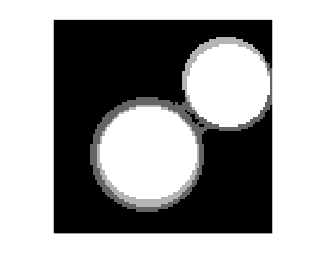

im = imread("Circle.tif");
if size(im,3) == 3;  im = rgb2gray( im ); end
imshow( im,'InitialMagnification','fit' );

## Extract boundaries and find control points

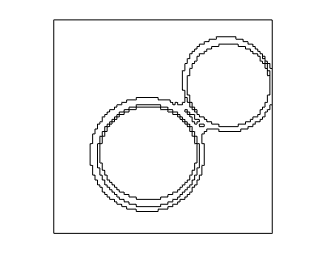

% image to polygon boundary
boundsRaw = im2Bounds( im );

% label control points
tf_avoid_sharp_corner = false;
boundsCtrlP = getCtrlPnts( boundsRaw, tf_avoid_sharp_corner, size(im) );

plotBounds(boundsCtrlP);     

## Smooth boundary

Set thresholds to zero.

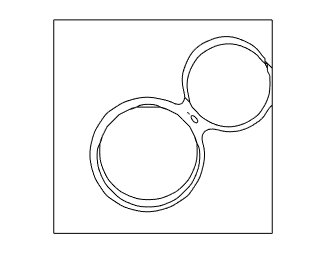

lambda = 0.5;
mu = -0.5;
iters = 100;
threshold_num_turning = 0;
threshold_num_vert_Smo = 0;

boundsSmooth = smoothBounds( boundsCtrlP, lambda, mu, iters, ...
                threshold_num_turning, threshold_num_vert_Smo );

plotBounds(boundsSmooth);

It seems that some boundaries are over-smoothed. Let's zoom in to check that.

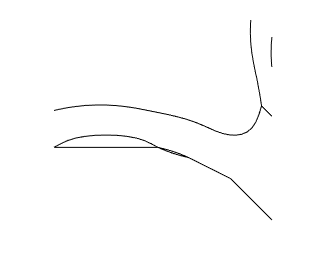

plotBounds(boundsSmooth);

xlim([34.5 55.5])
ylim([44.2 64.8])

## Compare

We can compare boundsSmooth with boundsRaw. Here, we use function plotBounds2 to plot these two boundaries in the same figure.

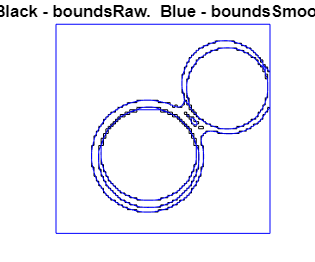

plotBounds2( boundsRaw, boundsSmooth );

Let's zoom in.

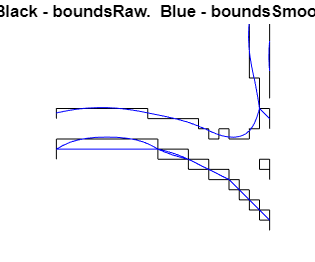

plotBounds2( boundsRaw, boundsSmooth );

xlim([34.5 55.5])
ylim([44.2 64.8])

We can see that boundsSmooth lost the details of the pristine boundaries. Some of the smoothed polygons have zero area. This is not what we want.

## Set threshold

Now, we set thresholds.

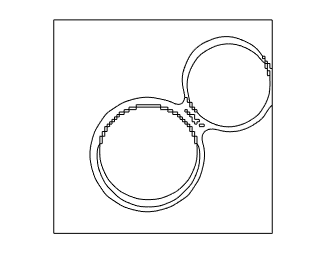

lambda = 0.5;
mu = -0.5;
iters = 100;
threshold_num_turning = 10;
threshold_num_vert_Smo = 20;

boundsSmooth = smoothBounds( boundsCtrlP, lambda, mu, iters, ...
                threshold_num_turning, threshold_num_vert_Smo );

plotBounds(boundsSmooth);

Zoom in.

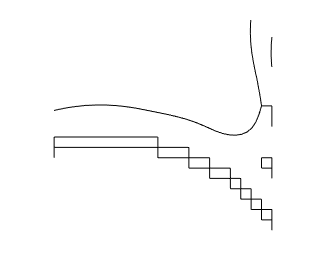

plotBounds(boundsSmooth);

xlim([34.5 55.5])
ylim([44.2 64.8])

It seems new boundaries are better. We can compare with the pristine boundaries.

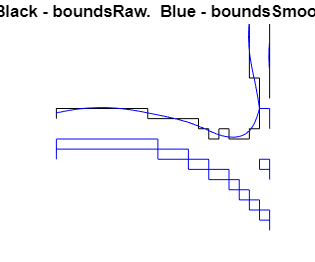

plotBounds2( boundsRaw, boundsSmooth );

xlim([34.5 55.5])
ylim([44.2 64.8])

Very good.

% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo